# **JacobiSN**

Jacobi elliptic function *sn*

## Definition


$$\textrm{sn}\left(x\left|m\right.\right)\equiv \sin \left(\textrm{am}\left(x\left|m\right.\right)\right)$$



$$\textrm{sn}\left(x,k\right)\equiv \textrm{sn}\left(x\left|k^2 \right.\right)$$


where *am* is the Jacobi amplitude function, $-\infty <x<\infty$, $-\infty <m<\infty$ is the parameter and $\left|-\infty <k<\infty \right.$ is the modulus. For the specified domain, the  codomain of *sn *are real numbers.

Basic features:

$\mathrm{sn}\left(x+4K\left|m\right.\right)=\mathrm{sn}\left(x\left|m\right.\right)$  (periodic) ,  $\mathrm{sn}\left(-x\left|m\right.\right)=-\mathrm{sn}\left(x\left|m\right.\right)$ (odd)

Special values:


$$\mathrm{sn}\left(0|m\right)=0$$


$\mathrm{sn}\left(x|0\right)=\mathrm{sin}\left(x\right)$,  $\mathrm{sn}\left(x|1\right)=\mathrm{tanh}\left(x\right)$

## Syntax

Y = JacobiSN(X,K)

y = jsn(x,k)

Y = mJacobiSN(X,M)

y = mjsn(x,m)

## Description

Y = JacobiSN(X,K) returns the Jacobi elliptic function $\textrm{sn}\left(x,k\right)$ for each element of the arrays X and K (modulus). X and K must be real and the same size or any of them can be scalar. **JacobiSN** is the wrapper function which calls the functions **jsn** element-wise via the function **ufun2**.

y = jsn(x,k) returns the Jacobi elliptic function $\mathrm{sn}\left(x,k\right)$ for argument x and the modulus k. It is assumed that  arguments are real scalars without check. The function returns NaN if either of  the arguments is invalid or convergence failed. **jsn** is the wrapper function which calls the functions **sncndn**.

Y = mJacobiSN(X,M) returns the Jacobi elliptic function $\mathrm{sn}\left(x|m\right)$ for each element of the arrays X and M (parameter). X and M must be real and the same size or any of them can be scalar. **mJacobiSN** is the wrapper function which calls the function **mjsn** element-wise via the function **ufun2**.

y = mjsn(x,m) returns the Jacobi elliptic function $\mathrm{sn}\left(x|m\right)$ for  argument x and the parameter m. It is assumed that  arguments are real scalars without check. The function returns NaN if either of  the arguments is invalid or convergence failed.  **mjsn** is the wrapper function which calls the function **sncndn**.

**sncndn **implements the AGM transformation for simultaneously  computation of the functions *sn*, *cn*, *dn* . For $m>1$ the Jacobi's transformation is used [1,2].

## Precision

For  $|m|\le 1$ the relative error of $\textrm{sn}\left(x\left|m\right.\right)$ is less than ${10}^{-10}$ when $|x|<{10}^4$. For  $\left|m\right|\le {10}^4$ the relative error of $\textrm{sn}\left(x\left|m\right.\right)$ is less than ${10}^{-9}$ when $|x|<{10}^4$.

## **Numerical Examples**

**Salar input**

jsn(0.5,0.5)

ans = 0.4751

mjsn(0.5,0.5)

ans = 0.4708

fprintf('%.16g\n',mjsn(3,5))

0.03114477815539745


*Note*. Exact value sn(3|5) =  `0.031144778155397``39`

**Vector of function values**

Create a column vector of domain values

x = (0:0.2:1)'

x =                    0
   0.200000000000000
   0.400000000000000
   0.600000000000000
   0.800000000000000
   1.000000000000000


Calculate the function values with k = 0.5

JacobiSN(x,0.5)

ans =                    0
   0.198345391214472
   0.387042423233959
   0.557733802371062
   0.704212141547168
   0.822635578129862


Create a row vector of parameter values

m = -1.5:0.5:1

m =   -1.500000000000000  -1.000000000000000  -0.500000000000000                   0   0.500000000000000   1.000000000000000


Calculate the function values at x = 0.5

mJacobiSN(0.5,m)

ans =    0.505676693206751   0.496891190419312   0.488139943371935   0.479425538604203   0.470750473655657   0.462117157260010


Calculate the function values for two array arguments

mJacobiSN([2 1 -3],[1 2 3])

ans =    0.964027580075817   0.672101903974327   0.577344237752229


mJacobiSN([2 1 -3]',[1 2 3]')

ans =    0.964027580075817
   0.672101903974327
   0.577344237752229


**Matrix of function values**

Create a matrix of domain values

X=[-1 0 1 2; 2 3 4 8];

Calculate the function values with parameter m = 2.

mJacobiSN(X,2)

ans =   -0.672101903974327                   0   0.672101903974327   0.522534006835699
   0.522534006835699  -0.352905016906534  -0.705521997854003  -0.132640610742556


Calculate the function values for two matrix arguments.

JacobiSN([2 1 -3; -1 2 3],[1 2 3; -1 2 3])

ans =    0.964027580075817   0.481449088799139  -0.214349536163710
  -0.761594155955765  -0.290100059906837   0.214349536163710


## **Graphs **

**Example 1**

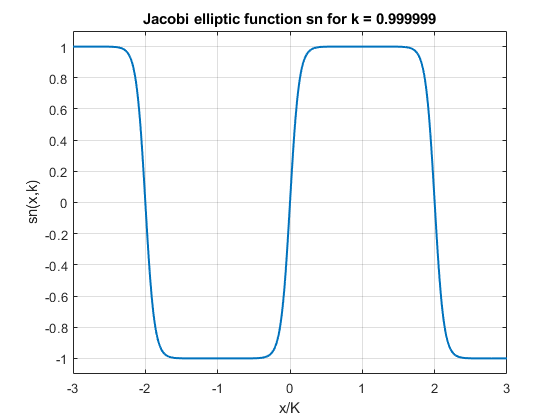

figure
x=-3:0.01:3;
k = 0.999999;
plot(x,JacobiSN(elK(k)*x,k),'LineWidth',1.5)
xlabel('x/K')
ylabel('sn(x,k)')
ylim([-1.1 1.1])
title(sprintf('Jacobi elliptic function sn for k = %g',k))
grid on

**Example 2**

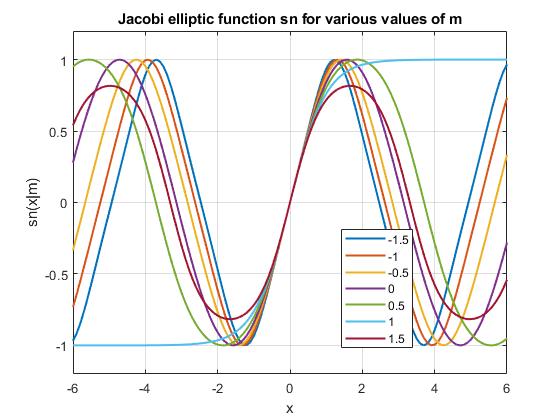

figure
X = -6:0.1:6;
M = -1.5:0.5:1.5;
SN = zeros(length(M),length(X));
clg{length(M)}=[];
for i = 1:length(M)
     clg{i} = num2str(M(i));
    SN(i,:) = mJacobiSN(X,M(i));
end
plot(X,SN,'LineWidth',1.5)
axis([min(X) max(X) -1.2 1.2])
grid on
legend(clg,'Location','Best')
title('Jacobi elliptic function sn for various values of m')
xlabel('x')
ylabel('sn(x|m)')

**Example 3**

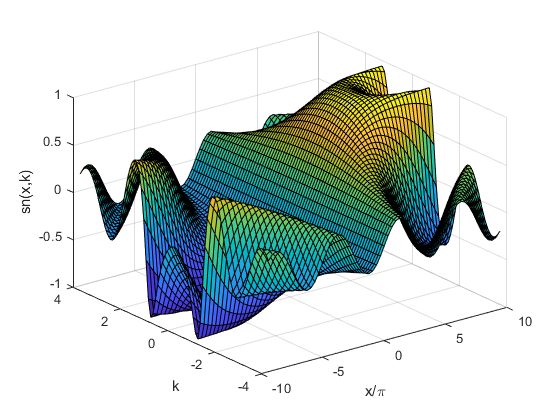

figure
x=-3:0.1:3;
k=-4:0.1:4;
[X,K]=meshgrid(x,k);
surface(pi*X,K,JacobiSN(X,K))
view(3)
xlabel('x/\pi')
ylabel('k')
zlabel('sn(x,k)')
grid on

**Example 4**

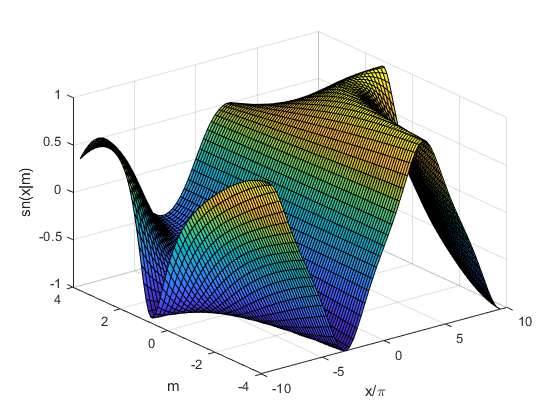

figure
x=-3:0.1:3;
m=-4:0.1:4;
[X,M]=meshgrid(x,m);
surface(pi*X,M,mJacobiSN(X,M))
view(3)
xlabel('x/\pi')
ylabel('m')
zlabel('sn(x|m)')
grid on

**Example 5**

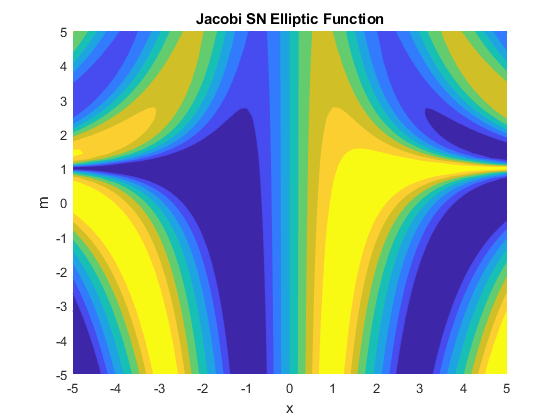

figure
f = @(x,m)mJacobiSN(x,m);
fcontour(f,'Fill','on')
title('Jacobi SN Elliptic Function')
xlabel('x')
ylabel('m')

## More About

[Abramowitz and Stegun. Handbook of Mathematical Functions](http://people.math.sfu.ca/~cbm/aands/frameindex.htm)

[Jacobian Elliptic Functions, NIST Digital Library of Mathematical Functions](https://dlmf.nist.gov/22)

[Jacobi elliptic functions, Wikipedia](https://en.wikipedia.org/wiki/Jacobi_elliptic_functions)

## **References**

[1] R. Bulirsch, Numerical Calculation of Elliptic Integrals and Elliptic Functions. Numerische Mathematik 7, 78-90, 1965

[2] W.H. Press et al., Numerical Recipes, 3rd ed., Cambridge, 2007

## See Also